This uses the simple propagator, implementing a periapsis burn.

First we define the satellite's characteristics. Approximately a 9U cubesat.

area = 1;       % m2
ref = 0.08;     % NA
initMass = 10;  % kg
endMass = 8;    % kg
isp = 2150;     % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 0.001; % N
mDot = 52e-9;   % kg/s

And the orbit's intial conditions. The model needs the semimajor axis, so we add Earth's radius.

earthRadius = 6378136.3;    % m
% [sma,ecc,inc,RAAN,aop,true_an] = deal(250e3+earthRadius, 0.01, 25, 0, 135, -20); % LEO
% [sma,ecc,inc,RAAN,aop,true_an] = deal(24371e3, 0.73, 25, 0, 135, -20); % GTO
p = 1.35e8; f = 3.6e8; sma = (p+f)/2; ecc = (f-p)/(f+p);
[inc,RAAN,aop,true_an] = deal(29, 0, 135, -85);
startDate = juliandate(datetime(2024, 03, 01));

If `burnOverride` is set to 0, we can specify the maneouvre strategy. We will only allow the satellite to burn at periapsis to make use of the Oberth effect.

burnOverride = 0;
% thrustingThreshold = sma*(1-ecc)+1000e3;
thrustingThreshold = 0.90;
thrustingThresholdMn = 0.999;
% thrustingThreshold = 100e3+earthRadius;

Now choose a simulation length and run it.

% tf = 15; tf = tf * 30 * 24 * 3600;
tf = 50* 24 * 3600;
% open_system('propagatorSimple.slx');
tic;
simOut = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.192s


toc

Elapsed time is 14.522303 seconds.


We extract the data from the simulation. This being the satellite's position and its attitude, and the Moon's position in order to obtain a trajectory line.

tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
tsSatAtt = simOut.yout{3}.Values;
ttSatAtt = timeseries2timetable(tsSatAtt);
tsSatVel = simOut.yout{2}.Values;
ttSatVel  = timeseries2timetable(tsSatVel);
tsMoon = simOut.yout{5}.Values;
ttMoon = timeseries2timetable(tsMoon);

To avoid conflicts with the viewer's trajectory interpolation, we retime the timetables manually (this is needed as of R2023b, but may be fixed in future updates).

ttSat = retime(ttSat,'minutely');
ttSatAtt = retime(ttSatAtt,'minutely');
ttSatVel = retime(ttSatVel, 'minutely');
ttMoon = retime(ttMoon,'minutely');

Raw plot

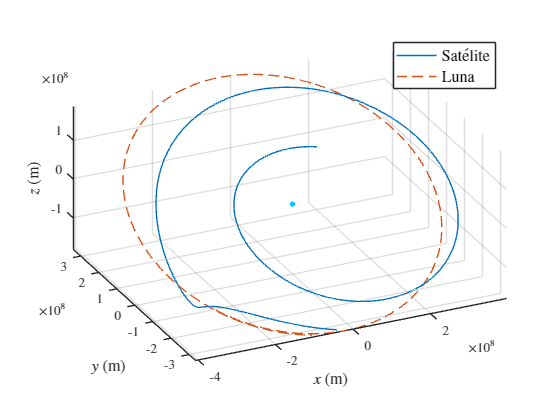

tic
figure
[X,Y,Z] = sphere();
s = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(s, 'edgecolor', 'none', 'FaceColor', [0,200,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1), ttSat.Data(:,2), ttSat.Data(:,3), DisplayName="$\mathrm{Sat\acute{e}lite}$")
plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), '--', DisplayName='$\mathrm{Luna}$')
legend(Interpreter="latex", FontSize=12, Location="northeast")
axis equal
daspect([1 1 1])
% view([-6 52])
% view([-12 40])
view([-25 25])
xlabel('$x$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
ylabel('$y$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
zlabel('$z$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
set(gca,'TickLabelInterpreter','latex')

% exportgraphics(gcf,'C:\Users\miqui\OneDrive\University\4º 23-24\TFG\LaTeX\img\GTOfullBurn.png', Resolution=300)
toc

Elapsed time is 0.124183 seconds.


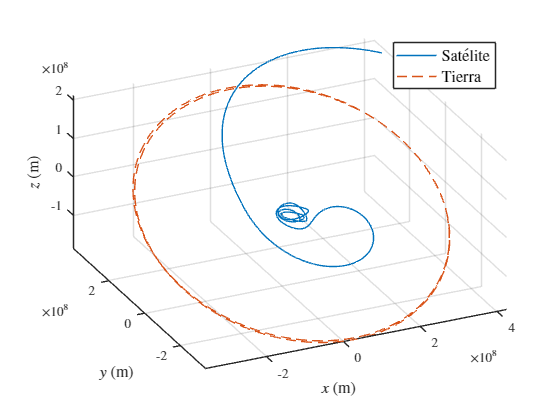

tic
moonRadius = 1737e3;
figure
[X,Y,Z] = sphere();
s = surf(X*moonRadius, Y*moonRadius, Z*moonRadius); % plot the Moon at the centre
set(s, 'edgecolor', 'none', 'FaceColor', [100,100,100]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1)-ttMoon.Data(:,1), ...
    ttSat.Data(:,2)-ttMoon.Data(:,2), ttSat.Data(:,3)-ttMoon.Data(:,3), DisplayName="$\mathrm{Sat\acute{e}lite}$")
plot3(-ttMoon.Data(:,1), -ttMoon.Data(:,2), -ttMoon.Data(:,3), '--', DisplayName='$\mathrm{Tierra}$')
legend(Interpreter="latex", FontSize=12, Location="northeast")
axis equal
daspect([1 1 1])
view([-25 25])
xlabel('$x$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
ylabel('$y$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
zlabel('$z$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
% lim = moonRadius+10e6;
% xlim([-lim lim])
% ylim([-lim lim])
% zlim([-lim lim])
set(gca,'TickLabelInterpreter','latex')

% exportgraphics(gcf,'C:\Users\miqui\OneDrive\University\4º 23-24\TFG\LaTeX\img\lunarCaptureMCI.png', Resolution=300)
toc

Elapsed time is 0.123993 seconds.


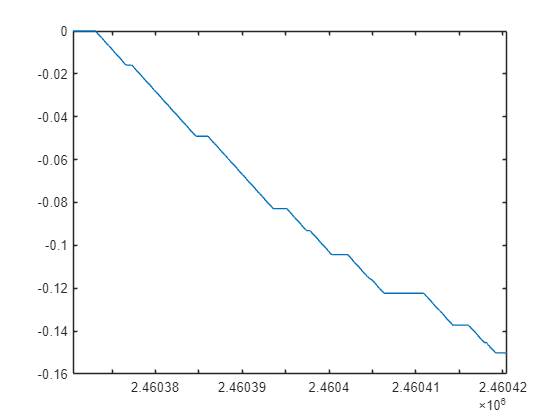

figure
plot(simOut.yout{4}.Values.Data, simOut.yout{6}.Values.Data)
xlim([min(simOut.yout{4}.Values.Data), max(simOut.yout{4}.Values.Data)])

Set up the viewer.

% t0 = datetime(2024, 03, 01);
% tfin = t0 + seconds(tf);
% sample_time = 60;
% sc = satelliteScenario(t0,tfin,sample_time);

Create the satellite.

% sat = satellite(sc,ttSat,Name = "Spacecraft");

Add the Moon to the visualisation.

% moon = satellite(sc,ttMoon,Name= "Moon");
% moon.Orbit.LineColor = 'red';
% moon.MarkerColor = 'red';

Start the visualisation.

% v = satelliteScenarioViewer(sc,CameraReferenceFrame = "Inertial");
% play(sc)
% camtarget(v,moon);

r = ttSat(end,end).Data;
v = ttSatVel(end,end).Data;
[sma1,ecc1,inc1,RAAN1,aop1] = state2class(r, v, 1)

sma1 = 4.8346e+08

ecc1 = 0.2620

inc1 = 27.5075

RAAN1 = 3.5592

aop1 = 138.6703

p1 = sma1*(1-ecc1)

p1 = 3.5678e+08

f1 = sma1*(1+ecc1)

f1 = 6.1014e+08

usedMass = simOut.yout{6}.Values.Data(end)

usedMass = -0.1501